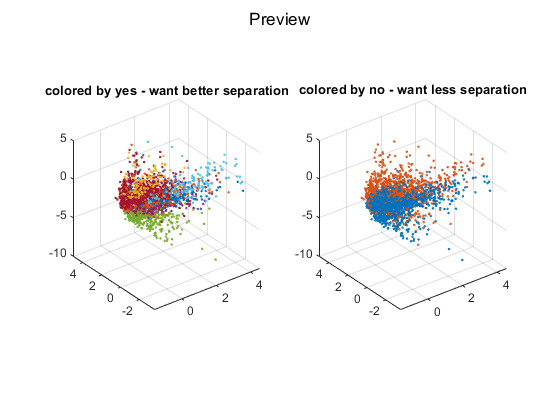

%%
close all
clear

rng(2019)
dataset = load('retina.mat');
patient = dataset.patient;
type = dataset.type;
dataset = dataset.expr;

c = 2;
n = size(dataset, 1);

no = patient;
yes = type;

dataset = dataset - mean(dataset, 1);
dataset = dataset ./ std(dataset, 1);

figure
sgtitle('Preview')
subplot(1, 2, 1)
for t = unique(type)'
    scatter3(dataset(yes == t, 1), dataset(yes == t, 2), dataset(yes == t, 3), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by yes - want better separation')

subplot(1, 2, 2)
scatter3(dataset(no == 1, 1), dataset(no == 1, 2), dataset(no == 1, 3), 2)
hold on
scatter3(dataset(no == 2, 1), dataset(no == 2, 2), dataset(no == 2, 3), 2)
pbaspect([1 1 1])
title('colored by no - want less separation')

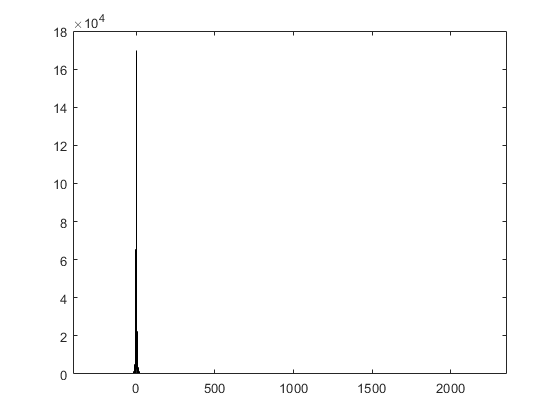

% symk = @(x) exp(-(mpdist(x) .^ 2) / (2 * 8 ^ 2)); % Gaussian RBF kernel
% symk = @(x) exp(mpdist(x) / 8); % Laplace RBF kernel
% symk = @(x) tanh(0.3 * x * x' + 0); % sigmoid kernel
% symk = @(x) (x * x' + 2) .^ 2; % polynomial kernel
% symk = @(x) (x * x'); % linear kernel
% symk = @

K = symk(dataset);

figure
histogram(K(:))


%% AAT

term2 = zeros(c);
for a = 1 : c
    for b = 1:(a - 1)
        term2(a, b) = mean(mean(K(no == a, no == b)));
        term2(b, a) = term2(a, b);
    end
    term2(a, a) = mean(mean(K(no == a, no == a)));
end

top = zeros(c, 1);
bot = zeros(c, 1);
num = zeros(c, 1);
for a = 1 : c
    num(a) = sum(no == a);
    if a == 1
        top(a) = 1;
    else
        top(a) = top(a - 1) + n - num(a - 1);
    end
    bot(a) = top(a) + n - num(a) - 1;
end

AAT = zeros((c - 1) * n);
for a = 1 : c
    for b = 1 : (a - 1)
        term4 = mean(K(no ~= a, no == b), 2);
        term3 = mean(K(no == a, no ~= b), 1);
        AAT(top(a) : bot(a), top(b) : bot(b)) = K(no ~= a, no ~= b) + term2(a, b) - term3 - term4;
        AAT(top(b) : bot(b), top(a) : bot(a)) = AAT(top(a) : bot(a), top(b) : bot(b))';
    end
    b = a;
    term4 = mean(K(no ~= a, no == b), 2);
    term3 = mean(K(no == a, no ~= b), 1);
    AAT(top(a) : bot(a), top(b) : bot(b)) = K(no ~= a, no ~= b) + term2(a, b) - term3 - term4;
end

AAT = AAT / eigs(AAT, 1);

th = 1e-12;
r = size(AAT, 1);

[u, s] = eigs(AAT, r);
s = diag(s);
mask = s / max(s) > th;
s = s(mask);
u = u(:, mask);

%% distances
term11 = zeros(n, c);
for a = 1 : c
    term11(:, a) = mean(K(:, no == a), 2);
end

ind1 = [];
ind2 = [];
for a = 1 : c
    ind1 = [ind1 find(no ~= a)'];
    ind2 = [ind2 (zeros(1, n - num(a)) + a)];
end

D = zeros(n);

%for ii = 1 : n
%    for jj = 1 : n
%        vec = K(ii, ind1) - K(jj, ind1) + term11(jj, ind2) - term11(ii, ind2);
%        D(ii, jj) = sqrt(sum((vec * u ./ s') .^ 2, 2));
%    end
%end

for jj = 1 : n
    vec = K(jj : n, ind1) - K(jj, ind1) + term11(jj, ind2) - term11(jj : n, ind2);
    D(jj : n, jj) = sqrt(sum((vec * u ./ s') .^ 2, 2));
end

D = D + (D' .* (1 - eye(n)));


%%

u = umap();
u.metric = 'precomputed';
R = u.fit(D);

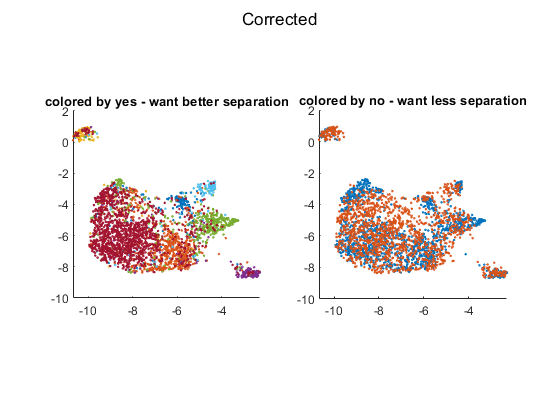

%R = tsne(D, [], 2);
%R = mdscale(D, 2);

figure
sgtitle('Corrected')
subplot(1, 2, 1)
for t = unique(type)'
    scatter(R(yes == t, 1), R(yes == t, 2), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by yes - want better separation')

subplot(1, 2, 2)
scatter(R(no == 1, 1), R(no == 1, 2), 2)
hold on
scatter(R(no == 2, 1), R(no == 2, 2), 2)
pbaspect([1 1 1])
title('colored by no - want less separation')